# Image Segmentation of Grayscale Image

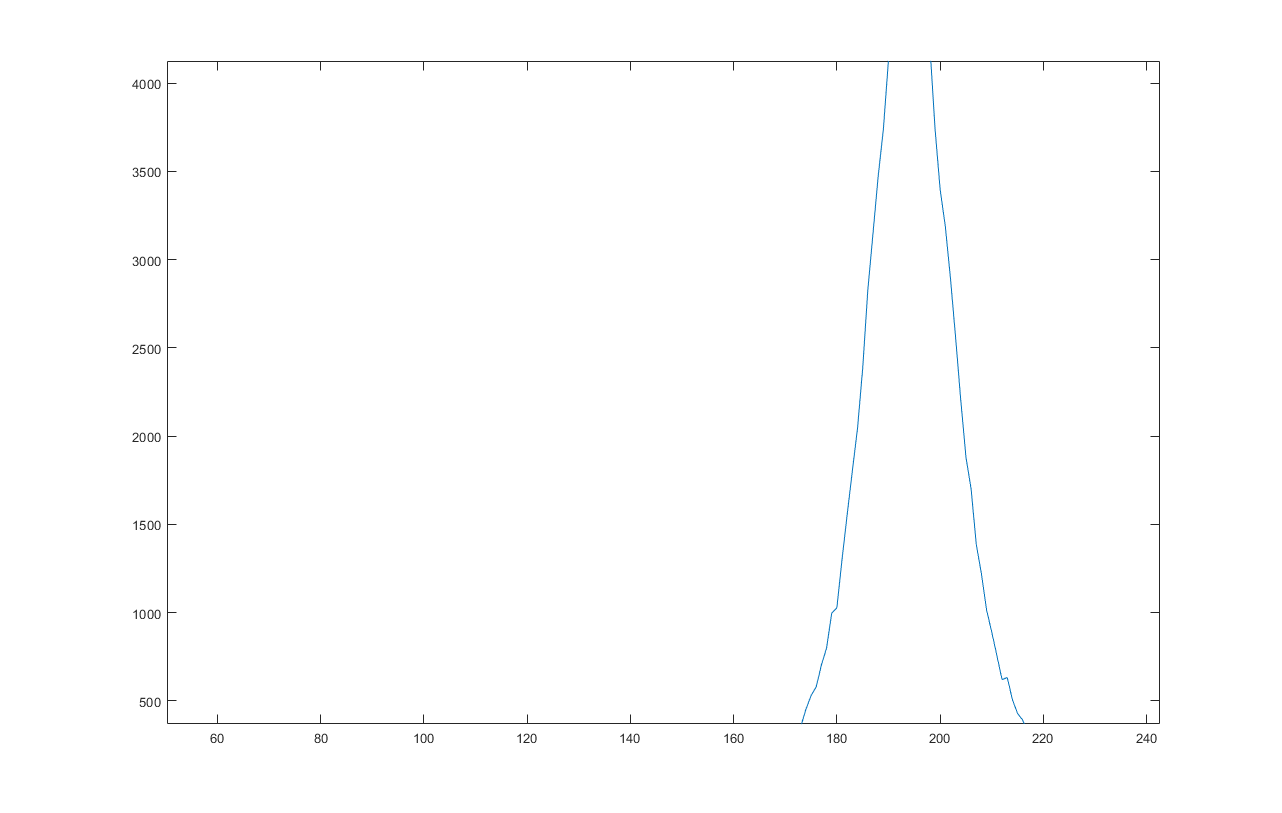

gray_im = imread('cropped_grayscale_check.jpg');
[counts, cells] = imhist(gray_im, 256);
plot(cells,counts); xlim([0 256]);

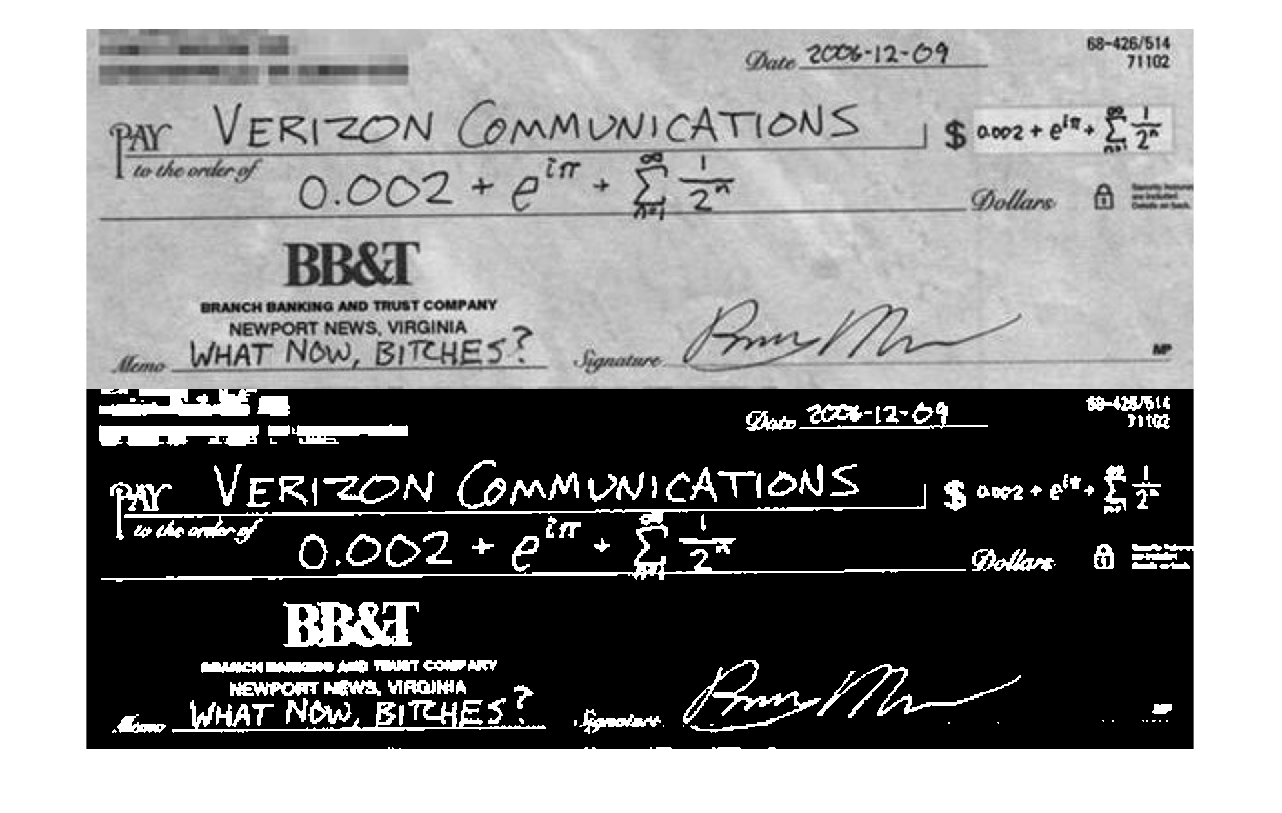

thresh = graythresh(gray_im);
bw_im = gray_im < 144;
% imshow(bw_im);
montage({gray_im, bw_im});

## Grayscale image then threshold

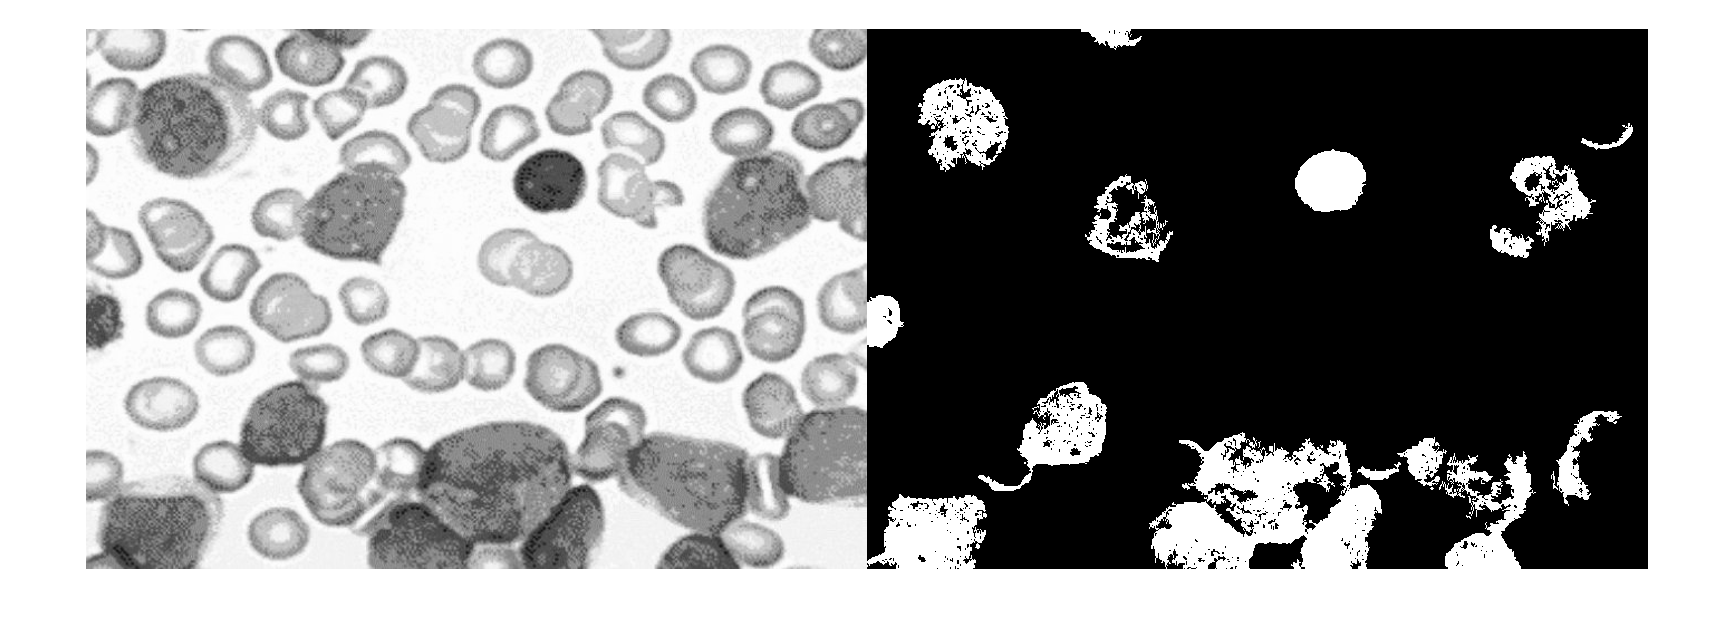

cancer_gray = imread('cancer.jpg');
cancer_gray = rgb2gray(cancer_gray);
% figure(); imshow(cancer_gray);
[counts2, cells2] = imhist(cancer_gray, 256);
% figure(); plot(cells2,counts2); xlim([0 256]);
cancer_bw = cancer_gray < 138;
% imshow(cancer_bw);
se = strel('disk',6);
bw2 = bwareaopen(cancer_bw,20);
bw2 = bwareaopen(bw2,20);
bw2 = bwareaopen(bw2,25);
bw2 = bwareaopen(bw2,30);
bw2 = bwareaopen(bw2,100);
bw2 = bwareaopen(bw2,250,8);
% bw2 = imclose(bw2,se);
montage({cancer_gray,bw2});

## Non-parametric Segmentation

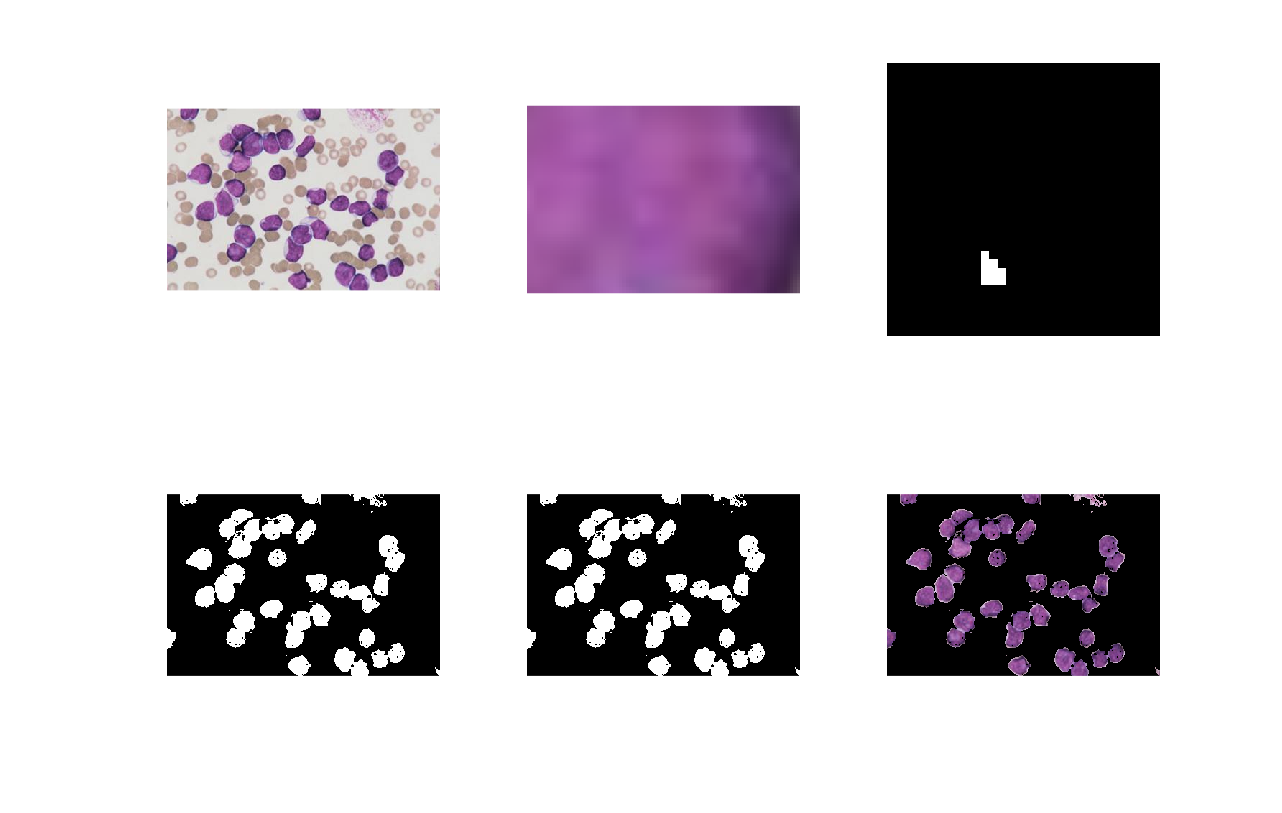

roi = imread('myeloroi2.png'); roi = double(roi); % change roi to file of choice
% imshow(roi);
R_roi = roi(:,:,1);
G_roi = roi(:,:,2);
B_roi = roi(:,:,3);
I = R_roi + G_roi + B_roi;
I(find(I==0)) = 100000;
r_roi = R_roi ./ I;
g_roi = G_roi ./ I;
BINS = 32;
r_roi_int = round(r_roi*(BINS-1) + 1);
g_roi_int = round(g_roi*(BINS-1) + 1);

colors = g_roi_int(:) + (r_roi_int(:)-1).*BINS;
histo = zeros(BINS,BINS);
for row = 1:BINS;
    for col = 1:(BINS-row+1);
        histo(row,col) = length(find(colors==(((col + (row-1)*BINS)))));
    end
end
% figure(1); imshow(imrotate(histo,90));

mbeth = imread('lympho.png'); mbeth = double(mbeth)/255; % change image to image file of choice
R_mbeth = mbeth(:,:,1);
G_mbeth = mbeth(:,:,2);
B_mbeth = mbeth(:,:,3);
I2 = R_mbeth + G_mbeth + B_mbeth;
I2(find(I2==0))=100000;
r_mbeth = R_mbeth ./ I2;
g_mbeth = G_mbeth ./ I2;

backproj = zeros(size(r_mbeth,1),size(r_mbeth,2));
for i = 1:size(r_mbeth,1)
    for j = 1:size(r_mbeth,2)
        rproj = round(r_mbeth(i,j)*(BINS-1)+1);
        gproj = round(g_mbeth(i,j)*(BINS-1)+1);
        backproj(i,j) = histo(rproj, gproj);
    end;    
end
% figure(2); imshow(backproj);
mask = repmat(backproj,1);
% mask = mask>0;
mask = mask/max(mask,[],'all');
a = find(mask>0&mask<1);
mask(a)=1;
mask = cast(mask,'like',mbeth);
seg = mbeth.*repmat(mask,[1,1,3]);
% figure(3); imshow(seg);
% montage({mask, seg})
figure(1);
subplot(2,3,1); imshow(mbeth);
subplot(2,3,2); imshow(uint8(roi));
subplot(2,3,3); imshow(imrotate(histo,90));
subplot(2,3,4); imshow(backproj);
subplot(2,3,5); imshow(mask);
subplot(2,3,6); imshow(seg);

## Parametric Segmentation (use ROI from previous section)

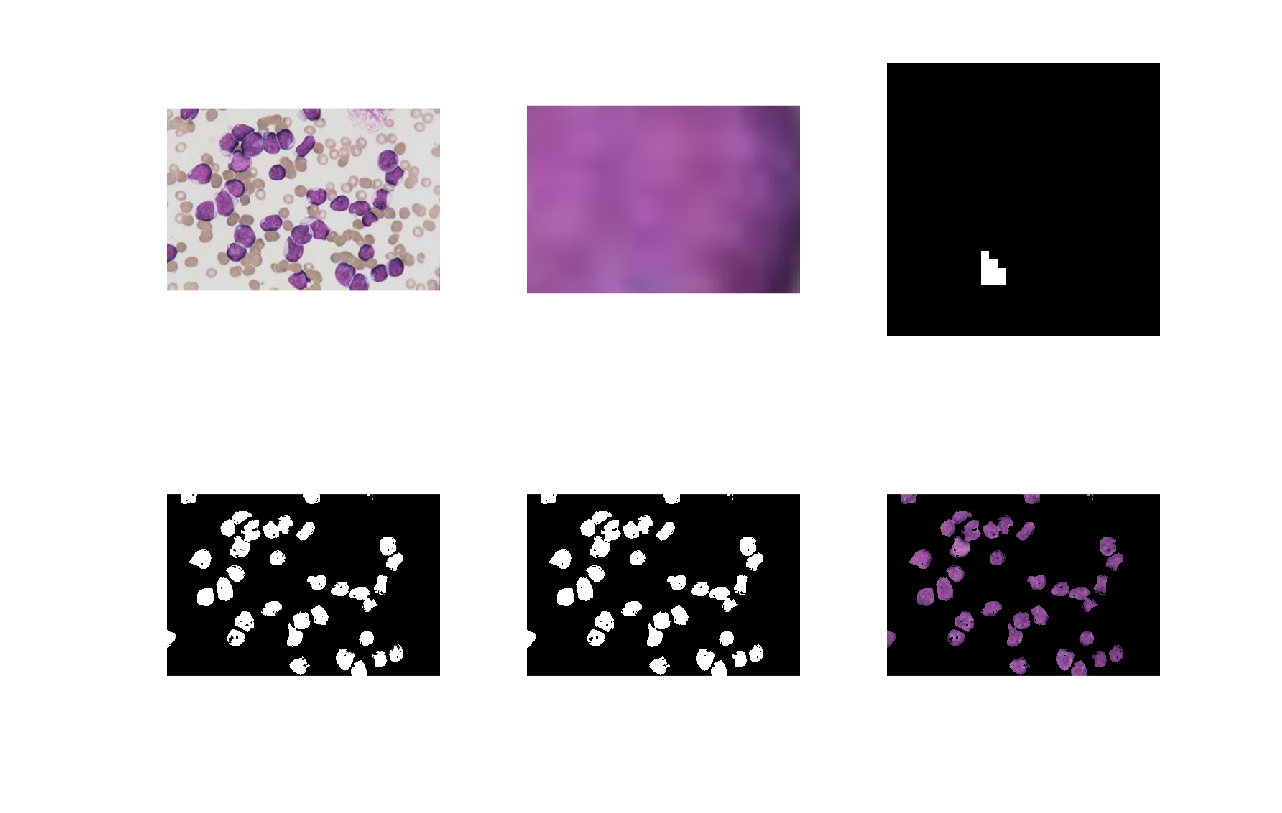

meanr = mean(r_roi,'all');
sigmar = std2(r_roi);
meang = mean(g_roi,'all');
sigmag = std2(g_roi);

pr = (1/(sigmar*sqrt(2*pi)))*exp(-((r_mbeth - meanr).^2)/(2*sigmar.^2));
pg = (1/(sigmag*sqrt(2*pi)))*exp(-((g_mbeth - meang).^2)/(2*sigmag.^2));
S = pr.*pg;

% imshow(S);

mask2 = repmat(S,1);
mask2 = mask2/max(mask2,[],'all');
b = find(mask2>1e-4&mask2<1);
mask2(b)=1;
% mask2 = mask2<1;
mask2 = cast(mask2,'like',mbeth);
seg2 = mbeth.*repmat(mask2,[1,1,3]);
% imshow(S);
% montage({seg2, mask2})
subplot(2,3,1); imshow(mbeth);
subplot(2,3,2); imshow(uint8(roi));
subplot(2,3,4); imshow(S);
subplot(2,3,5); imshow(mask2);
subplot(2,3,6); imshow(seg2);